clear all
close all
clc

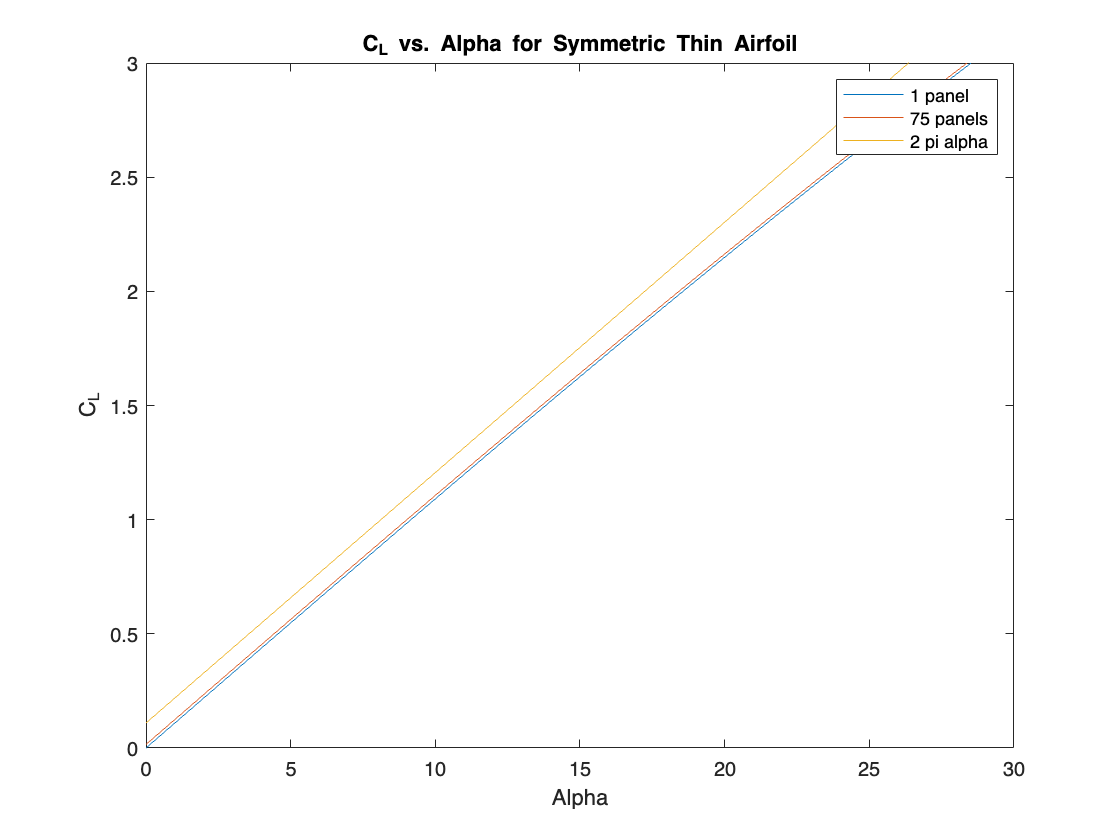

% Problem 1
for alpha=1:31

    [~,C_l,~,~,~,~,~,~] = computePanelData(10,-1000,alpha-1,1,1);
    Cl_1_panel(alpha)=C_l;

    [~,C_l,~,~,~,~,~,~] = computePanelData(10,-1000,alpha-1,75,1);
    Cl_75_panel(alpha)=C_l;

    Cl_eqn(alpha)= 2*pi*(alpha*(pi/180));

end

alpha = linspace(0,30,31);
Cl_combined = [Cl_1_panel;Cl_75_panel;Cl_eqn];
plot(alpha,Cl_combined);
title('C_L vs. Alpha for Symmetric Thin Airfoil')
xlabel('Alpha')
ylabel('C_L')
legend('1 panel', '75 panels', '2 pi alpha')
ylim([0,3])
xlim([0,30])

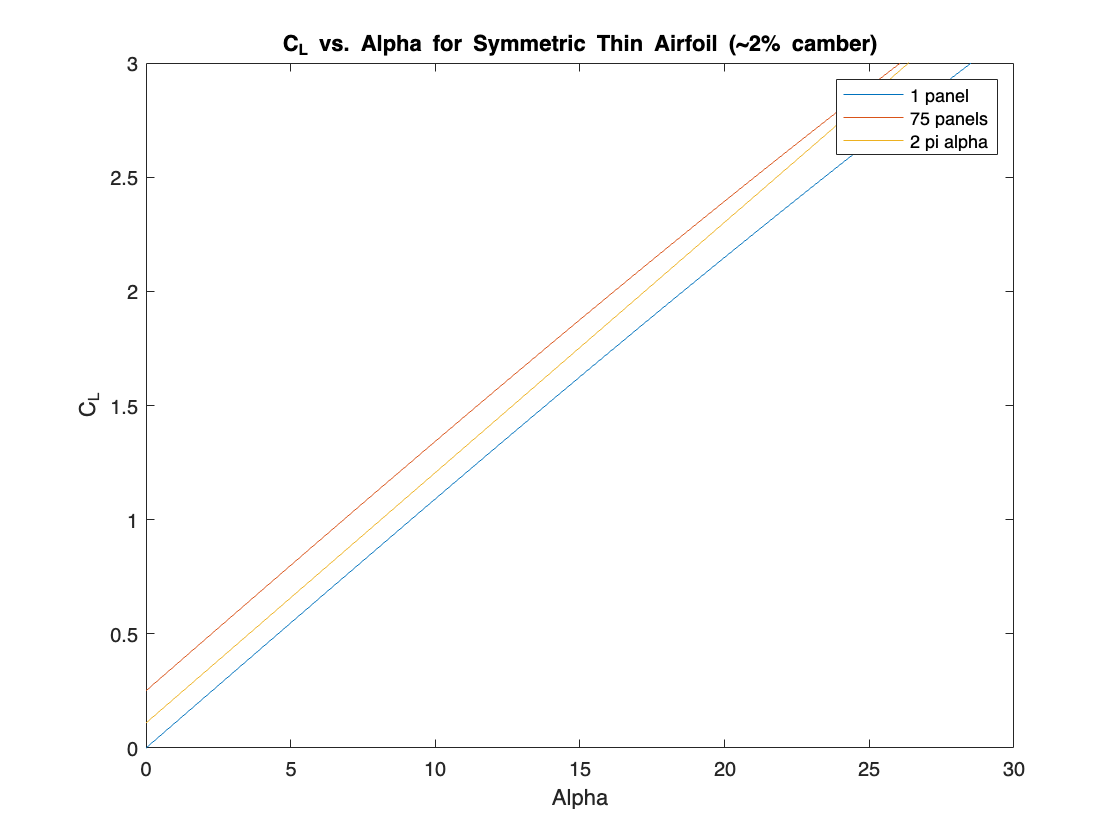

% Problem 2

for alpha=1:31

    [~,C_l,~,~,~,~,~,~] = computePanelData(10,-62,alpha-1,1,1);
    Cl_1_panel(alpha)=C_l;

    [~,C_l,~,~,~,~,~,~] = computePanelData(10,-62,alpha-1,75,1);
    Cl_75_panel(alpha)=C_l;

    Cl_eqn(alpha)= 2*pi*(alpha*(pi/180));

end

alpha = linspace(0,30,31);

Cl_combined = [Cl_1_panel; Cl_75_panel; Cl_eqn];

plot(alpha,Cl_combined);
title('C_L vs. Alpha for Symmetric Thin Airfoil (~2% camber)')
xlabel('Alpha')
ylabel('C_L')
legend('1 panel', '75 panels', '2 pi alpha')
ylim([0,3])
xlim([0,30])

% Problem 3 

[gamma,~,~,~,~,~,~,~] = computePanelData(10,-1000,5,75,1);

circulation = sum(gamma)

circulation = 28.1533

circulation_eqn = 10*10*pi*5*(pi/180)

circulation_eqn = 27.4156

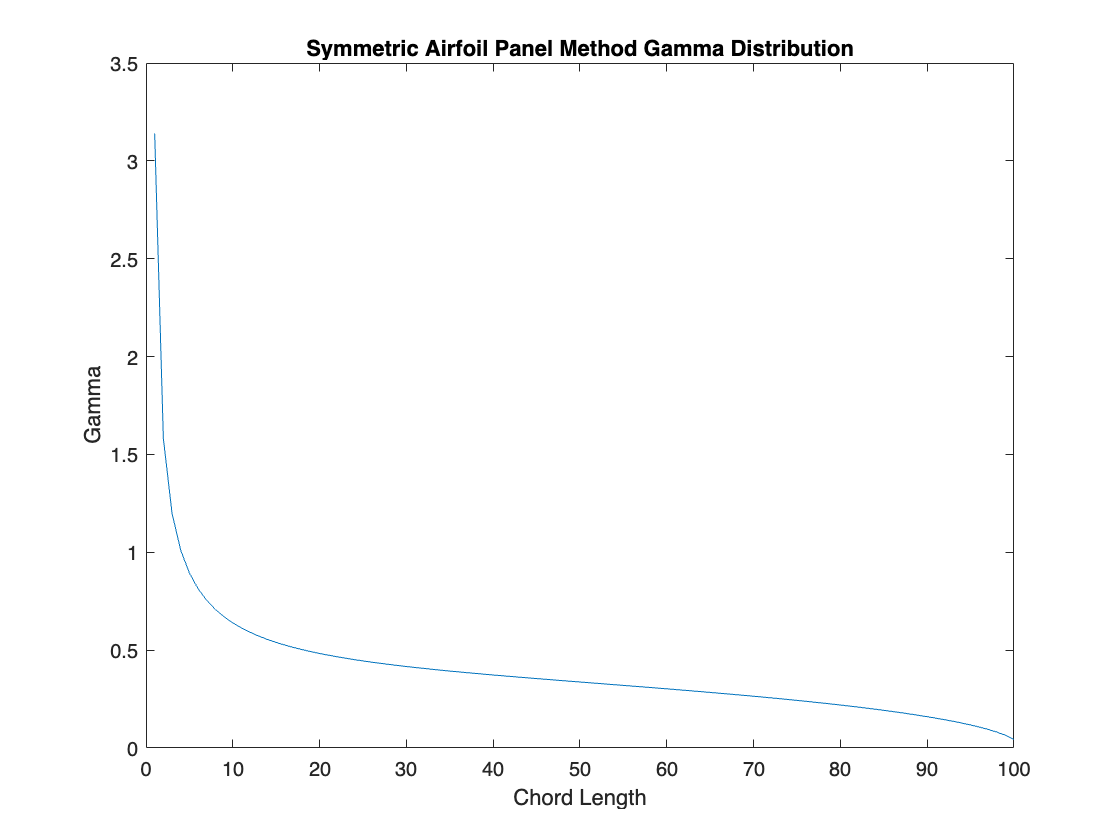

% Problem 4

[gamma,~,camber,~,~,~,~,~] = computePanelData(10,-62,5,100,1);
l = linspace(1,length(gamma),length(gamma));
plot(l,gamma)
title('Symmetric Airfoil Panel Method Gamma Distribution');
xlabel('Chord Length');
ylabel('Gamma');

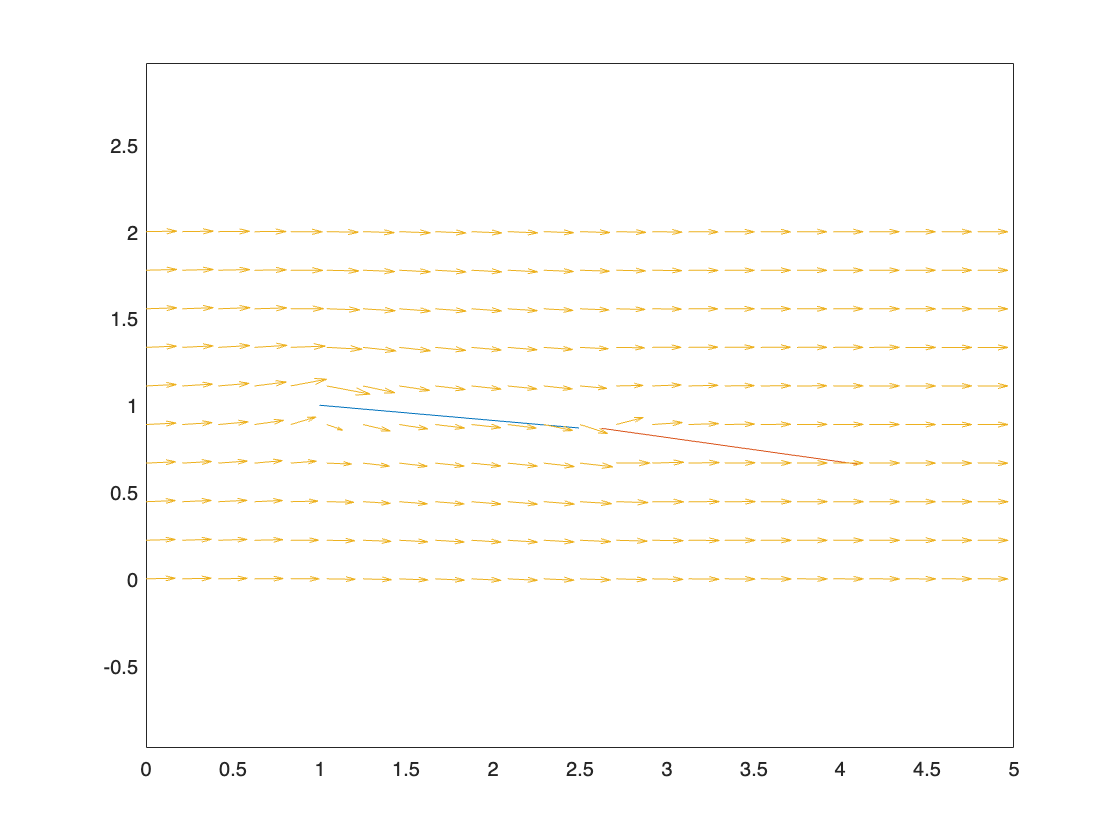

% Problem 5

N = 75;
% v_inf = 203.2; 
v_inf = 202.5;
% alpha_d = 4.68;
alpha_d = 0;
alpha_r = alpha_d*(pi/180);
grid_res = 5;
v_inf_x = v_inf*cos(alpha_r);
v_inf_y = v_inf*sin(alpha_r);
rho = 0.00238; 

% create the upstream airfoil
x_i_u = 1;
y_i_u = 1;
x_f_u = 2.494;
y_f_u = 0.869;

% create the downstream airfoil
x_i_d = 2.624;
y_i_d = 0.867;
x_f_d = 4.109;
y_f_d = 0.659;

% compute points for the upstream airfoil
x_u = linspace(x_i_u,x_f_u,N+1);
y_u = linspace(y_i_u,y_f_u,N+1);
plot(x_u,y_u);

hold on

% compute points for the downstream airfoil
x_d = linspace(x_i_d,x_f_d,N+1);
y_d = linspace(y_i_d,y_f_d,N+1);
plot(x_d,y_d);

axis equal
xlim([0,5])
ylim([0,2])

% creating the panels
            
panel_coords_g = zeros(N,4); 
panel_coords_g_u = zeros(N,4); 
panel_coords_g_d = zeros(N,4); 

for i=1:N
    panel_coords_g_u(i, 1) = x_u(i);
    panel_coords_g_u(i, 2) = y_u(i);
    panel_coords_g_u(i, 3) = x_u(i+1);
    panel_coords_g_u(i, 4) = y_u(i+1);
end

for i=1:N
    panel_coords_g_d(i, 1) = x_d(i);
    panel_coords_g_d(i, 2) = y_d(i);
    panel_coords_g_d(i, 3) = x_d(i+1);
    panel_coords_g_d(i, 4) = y_d(i+1);
end

panel_coords_g =[panel_coords_g_u; panel_coords_g_d];

% declaring panel length

L = 1.5/N;

% calculating the normal and tangential vectors

x_g = zeros(2*N,2);
for i=1:2*N
    x_g(i,1) = (panel_coords_g(i,3)-panel_coords_g(i,1))/L; 
    x_g(i,2) = (panel_coords_g(i,4)-panel_coords_g(i,2))/L; 
end

y_g = zeros(2*N,2);
y_g = [0 1; -1 0]*transpose(x_g);
y_g = -transpose(y_g);

% computing collocation points in global frame
collocation_g = zeros(2*N,2);
for i=1:2*N
    collocation_g(i,1) = panel_coords_g(i,1) + 0.75*L*x_g(i,1);
    collocation_g(i,2) = panel_coords_g(i,2) + 0.75*L*x_g(i,2);
end

% creating icm
icm = zeros(2*N, 2*N);
for i=1:2*N
    for j=1:2*N
        % x and y distances
        x_dist = collocation_g(j,1) - panel_coords_g(i,1);
        y_dist = collocation_g(j,2) - panel_coords_g(i,2);

        % Panel Velocity (i frame)  
        u_p = (1/(2*pi)) * (y_dist / ((y_dist)^2 + (x_dist-.25*L)^2)); 
        v_p = (-1/(2*pi)) * ((x_dist-.25) / ((y_dist)^2 + (x_dist-.25*L)^2 ));
        
        % Panel Velocity (global frame)
        B = inv([x_g(i,1) y_g(i,1); x_g(i,2) y_g(i,2)]);
        A = [u_p v_p];
        C = A * B;

        % updating icm matrix entry
        icm(j,i) = dot(C,y_g(j,:));
    end
end

% computing v_infinity normal and calculating gamma

v_inf_norm = zeros(2*N,1);
for i=1:2*N
    v_inf_norm(i) = -dot([v_inf_x, v_inf_y], y_g(i,:));
end
gamma = icm \ v_inf_norm;

% visualizing flow
mesh_X = linspace(0,5,5*grid_res);
mesh_Y = linspace(0,2,2*grid_res);
[X,Y]=meshgrid(mesh_X,mesh_Y);
dim_x = length(mesh_X);
dim_y = length(mesh_Y);
U = zeros(dim_y, dim_x);
V = zeros(dim_y, dim_x);

for i=1:dim_y
    for j=1:dim_x
        u_p_g = 0;
        v_p_g = 0;
        for k=1:2*N 
            x = mesh_X(j) - panel_coords_g(k,1);
            y = mesh_Y(i) - panel_coords_g(k,2);
    
            u_p = (gamma(k)/(2*pi)) * (y/((y^2)+((x-.25*L)^2)));
            v_p = (-gamma(k)/(2*pi)) * ((x-.25*L)/((y^2)+((x-.25*L)^2)));
    
            B = inv([x_g(k,1) y_g(k,1); x_g(k,2) y_g(k,2)]);
            A = [u_p v_p];
            C = A * B;
                
            u_p_g = u_p_g + C(1);
            v_p_g = v_p_g + C(2);
        end

        U(i,j) = v_inf_x + u_p_g;
        V(i,j) = v_inf_y + v_p_g;
    end
end

quiver(X,Y,U,V);
h=gca; h.XAxis.TickLength = [0 0];
h=gca; h.YAxis.TickLength = [0 0];
axis equal
% title()
hold off

lift = sum(gamma)*v_inf*rho

lift = 17.4098